# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240210_1'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'social_multiflavor_foraging'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {"14447","11827","29924","14406","14561","14633","14662","14531","71050","9776"}; % in order of serial number list
bname_ephys = {'14633','14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [2,1,0,0; 1,2,0,0; 2,1,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14633 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14633\20240210_093742_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14633" -interp 0
Using the following workspace file:  "20240210_093742_merged.trodesconf"
Exporting data...
1.143%2.285%3.427%4.57%5.712%6.854%A gap of 87 packets occured in the file. Last timestamp:  15612208 (Clock is:  "00:08:40" )
7.996%9.139%A gap of 145 packets occured in the file. Last timestamp:  19615902 (Clock is:  "00:10:53" )
A gap of 50 packets occured in the file. Last timestamp:  19616230 (Clock is:  "00:10:53" )
A gap of 33 packets occure

chanmap_file = struct with fields:
       name: '20240210_093742_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14633\20240210_093742_merged.kilosort'
       date: '11-Feb-2024 09:40:28'
      bytes: 5253
      isdir: 0
    datenum: 7.3929e+05


Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14662 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14662\20240210_093742_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14662" -interp 0
Using the following workspace file:  "20240210_093742_merged.trodesconf"
Exporting data...
A gap of 15 packets occured in the file. Last timestamp:  4911069 (Clock is:  "00:02:43" )
0.9976%1.995%2.992%A gap of 174 packets occured in the file. Last timestamp:  10734527 (Clock is:  "00:05:57" )
3.99%4.987%5.985%6.982%A gap of 25 packets occured in the file. Last timestamp:  18478865 (Clock is:  "00:10:15" )
7.979%8.977%9.974%A gap of 2 pac

chanmap_file = struct with fields:
       name: '20240210_093742_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14662\20240210_093742_merged.kilosort'
       date: '11-Feb-2024 11:18:55'
      bytes: 5253
      isdir: 0
    datenum: 7.3929e+05


### Run kilosort

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14633\20240210_093742_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  22s. Loading raw data and applying filters... 
Time 557s. Finished preprocessing 1202 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1534

0.44 sec, 1 batches, 10000 spikes 
40.22 sec, 101 batches, 1003578 spikes 
85.37 sec, 201 batches, 2002633 spikes 
130.86 sec, 301 batches, 3002407 spikes 
179.69 sec, 401 batches, 3999193 spikes 
231.97 sec, 501 batches, 4993832 spikes 
287.83 sec, 601 batches, 5983413 spikes 
346.84 sec, 701 batches, 6974159 spikes 
411.11 sec, 801 batches, 7968778 spikes 
478.69 sec, 901 batches, 8957220 spikes 
554.96 sec, 1001 batches, 9954480 spikes 
634.16 sec, 1101 batches, 10948682 spikes 
718.58 sec, 1201 batches, 11942643 spikes 
719.50 sec, 1202 batches, 11942879 spikes 


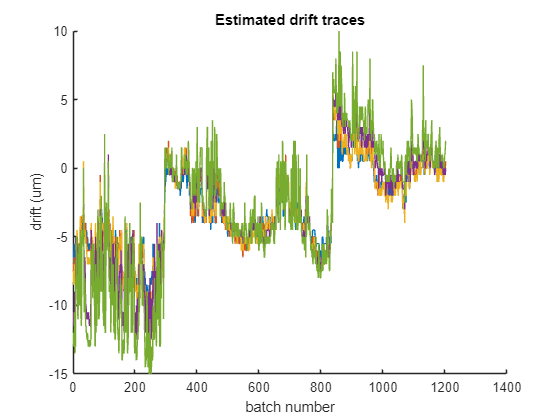

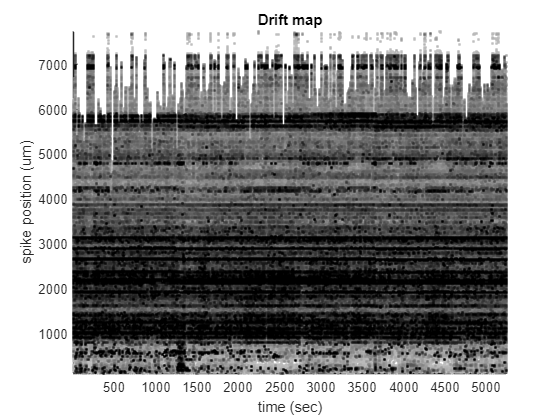

time 1827.21, Shifted up/down 1202 batches. 
0.93 sec, 1 batches, 10000 spikes 
91.49 sec, 101 batches, 1010000 spikes 
181.70 sec, 201 batches, 2010000 spikes 
271.84 sec, 301 batches, 3010000 spikes 
361.88 sec, 401 batches, 4010000 spikes 
452.23 sec, 501 batches, 5010000 spikes 
542.54 sec, 601 batches, 6010000 spikes 
633.05 sec, 701 batches, 7010000 spikes 
724.57 sec, 801 batches, 8010000 spikes 
815.02 sec, 901 batches, 9010000 spikes 
905.34 sec, 1001 batches, 10010000 spikes 
996.21 sec, 1101 batches, 11010000 spikes 
1086.70 sec, 1201 batches, 12010000 spikes 
1087.69 sec, 1202 batches, 12010470 spikes 
time 0.00, GROUP 1/384, units 0 
time 2.03, GROUP 6/384, units 7 
time 3.63, GROUP 11/384, units 15 
time 5.53, GROUP 16/384, units 22 
time 8.01, GROUP 21/384, units 31 
time 16.03, GROUP 26/384, units 55 
time 19.27, GROUP 31/384, units 62 
time 21.53, GROUP 36/384, units 67 
time 24.26, GROUP 41/384, units 72 
time 26.57, GROUP 46/384, units 77 
time 31.16, GROUP 51/384, u

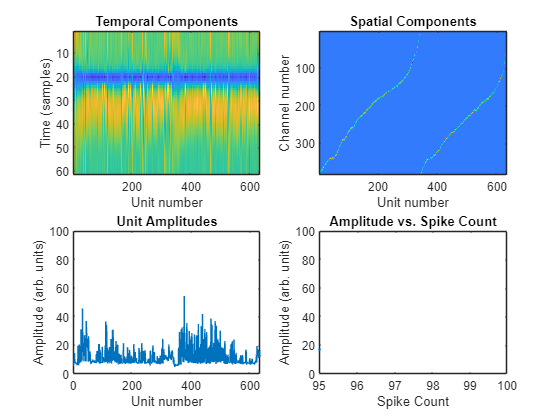

time 0.00, GROUP 1/384, units 0 
time 0.02, GROUP 6/384, units 0 
time 0.03, GROUP 11/384, units 0 
time 0.05, GROUP 16/384, units 0 
time 0.06, GROUP 21/384, units 0 
time 0.07, GROUP 26/384, units 0 
time 0.08, GROUP 31/384, units 0 
time 0.10, GROUP 36/384, units 0 
time 0.11, GROUP 41/384, units 0 
time 0.12, GROUP 46/384, units 0 
time 0.13, GROUP 51/384, units 0 
time 0.15, GROUP 56/384, units 0 
time 0.16, GROUP 61/384, units 0 
time 0.17, GROUP 66/384, units 0 
time 0.18, GROUP 71/384, units 0 
time 0.19, GROUP 76/384, units 0 
time 0.20, GROUP 81/384, units 0 
time 0.21, GROUP 86/384, units 0 
time 0.23, GROUP 91/384, units 0 
time 0.24, GROUP 96/384, units 0 
time 6.99, GROUP 101/384, units 13 
time 15.80, GROUP 106/384, units 27 
time 18.57, GROUP 111/384, units 32 
time 25.69, GROUP 116/384, units 41 
time 32.89, GROUP 121/384, units 52 
time 41.43, GROUP 126/384, units 66 
time 45.47, GROUP 131/384, units 73 
time 51.26, GROUP 136/384, units 81 
time 60.36, GROUP 141/384, 

ans = 111

initialized spike counts
merged 273 into 274 
merged 224 into 225 
merged 108 into 102 
merged 284 into 287 
merged 383 into 379 
merged 361 into 359 
merged 339 into 342 
merged 141 into 136 
merged 328 into 324 
merged 309 into 314 
merged 319 into 313 
merged 89 into 93 
merged 207 into 211 
merged 88 into 87 
merged 344 into 348 
merged 367 into 372 
merged 389 into 387 
merged 37 into 35 
merged 39 into 36 
merged 274 into 271 


ans = 96

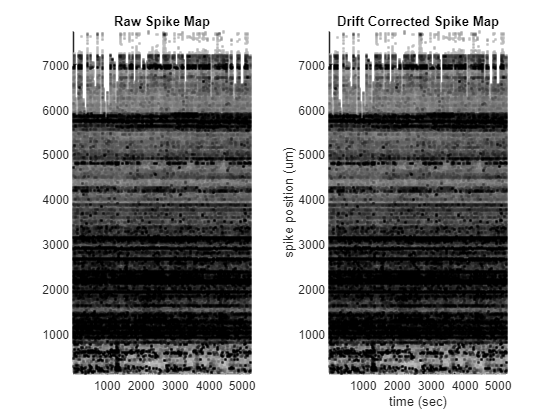

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [1202×1 double]
             dshift: [1202×5 double]
                st0: [11942879×6 double]
                  F: [1534×20×1202 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 

% 14633
path_to_rec_dir = dir(fullfile(data_dir,'ephys','*.rec','14633','*merged.rec')); path_to_rec_dir = path_to_rec_dir.folder;
probeNum = 1;
numChannels = 384;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_1\ephys\20240210_093742.rec\14662\20240210_093742_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  23s. Loading raw data and applying filters... 
Time 649s. Finished preprocessing 1376 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1534

0.40 sec, 1 batches, 4169 spikes 
40.46 sec, 101 batches, 485534 spikes 
83.39 sec, 201 batches, 950658 spikes 
129.45 sec, 301 batches, 1407736 spikes 
178.97 sec, 401 batches, 1840985 spikes 
231.61 sec, 501 batches, 2242125 spikes 
287.72 sec, 601 batches, 2644500 spikes 
347.21 sec, 701 batches, 3094862 spikes 
411.66 sec, 801 batches, 3495176 spikes 
482.12 sec, 901 batches, 3898337 spikes 
558.42 sec, 1001 batches, 4307554 spikes 
640.51 sec, 1101 batches, 4745987 spikes 
725.79 sec, 1201 batches, 5197329 spikes 
811.32 sec, 1301 batches, 5618068 spikes 
875.60 sec, 1376 batches, 5925465 spikes 


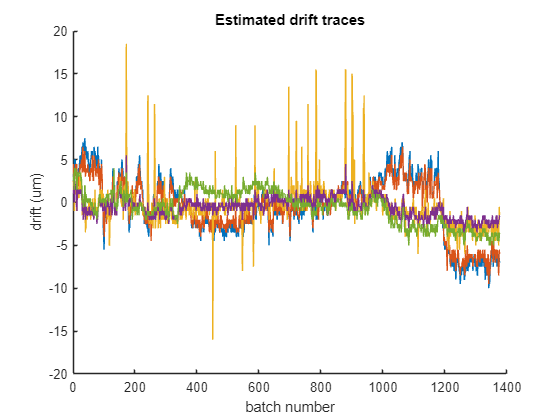

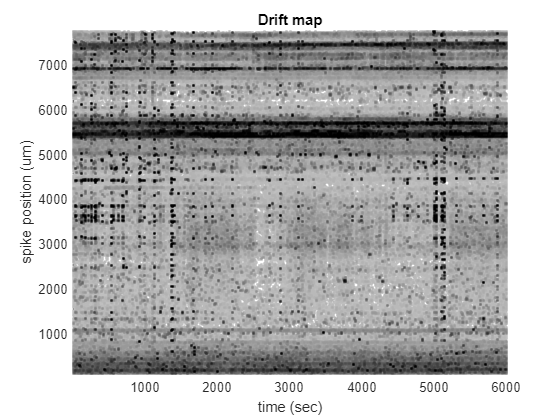

time 2136.40, Shifted up/down 1376 batches. 
0.91 sec, 1 batches, 10000 spikes 
91.64 sec, 101 batches, 1010000 spikes 
181.86 sec, 201 batches, 2010000 spikes 
272.36 sec, 301 batches, 3010000 spikes 
362.68 sec, 401 batches, 4010000 spikes 
453.51 sec, 501 batches, 5010000 spikes 
543.62 sec, 601 batches, 6010000 spikes 
633.66 sec, 701 batches, 7010000 spikes 
725.77 sec, 801 batches, 8010000 spikes 
817.64 sec, 901 batches, 9010000 spikes 
909.53 sec, 1001 batches, 10010000 spikes 
1002.26 sec, 1101 batches, 11010000 spikes 
1094.42 sec, 1201 batches, 12010000 spikes 
1187.62 sec, 1301 batches, 13009756 spikes 
1256.39 sec, 1376 batches, 13756178 spikes 
time 0.00, GROUP 1/384, units 0 
time 5.95, GROUP 6/384, units 12 
time 8.61, GROUP 11/384, units 19 
time 11.19, GROUP 16/384, units 27 
time 14.28, GROUP 21/384, units 38 
time 16.71, GROUP 26/384, units 47 
time 19.63, GROUP 31/384, units 57 
time 22.04, GROUP 36/384, units 67 
time 24.66, GROUP 41/384, units 78 
time 26.89, GRO

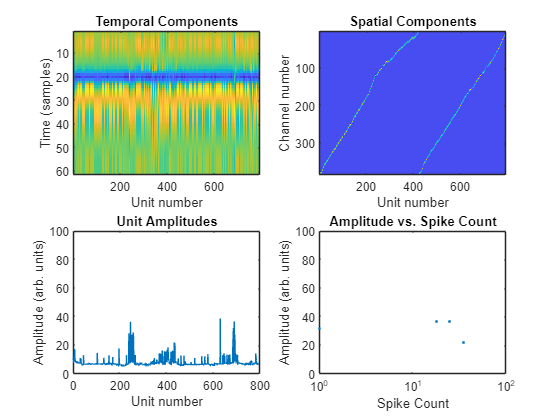

time 0.00, GROUP 1/384, units 0 
time 0.01, GROUP 6/384, units 0 
time 0.02, GROUP 11/384, units 0 
time 0.03, GROUP 16/384, units 0 
time 0.04, GROUP 21/384, units 0 
time 0.04, GROUP 26/384, units 0 
time 0.05, GROUP 31/384, units 0 
time 0.06, GROUP 36/384, units 0 
time 0.07, GROUP 41/384, units 0 
time 0.08, GROUP 46/384, units 0 
time 0.08, GROUP 51/384, units 0 
time 0.09, GROUP 56/384, units 0 
time 0.10, GROUP 61/384, units 0 
time 0.11, GROUP 66/384, units 0 
time 0.12, GROUP 71/384, units 0 
time 0.12, GROUP 76/384, units 0 
time 0.13, GROUP 81/384, units 0 
time 0.14, GROUP 86/384, units 0 
time 0.14, GROUP 91/384, units 0 
time 0.15, GROUP 96/384, units 0 
time 3.17, GROUP 101/384, units 12 
time 5.87, GROUP 106/384, units 22 
time 9.54, GROUP 111/384, units 32 
time 12.45, GROUP 116/384, units 41 
time 16.65, GROUP 121/384, units 50 
time 21.01, GROUP 126/384, units 58 
time 26.61, GROUP 131/384, units 66 
time 38.72, GROUP 136/384, units 83 
time 47.65, GROUP 141/384, un

ans = 36

initialized spike counts
merged 75 into 81 
merged 391 into 388 
merged 128 into 130 
merged 68 into 72 
merged 79 into 72 
merged 77 into 81 
merged 95 into 93 


ans = 31

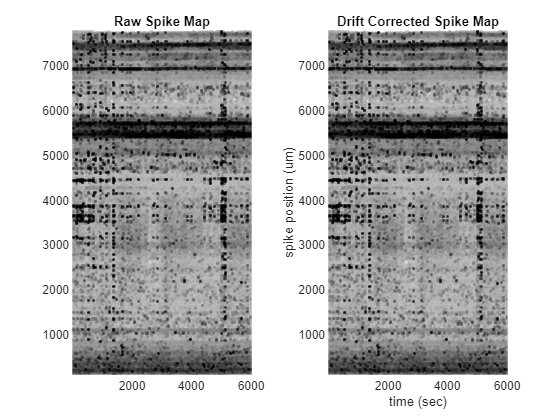

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [1376×1 double]
             dshift: [1376×5 double]
                st0: [5925465×6 double]
                  F: [1534×20×1376 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0


% 14662
path_to_rec_dir = dir(fullfile(data_dir,'ephys','*.rec','14662','*merged.rec')); path_to_rec_dir = path_to_rec_dir.folder;
probeNum = 1;
numChannels = 384;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)


disp('kilosort finished!')

kilosort finished!


## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);